## Setup and Variables


clear
close all
% data = readtable('./Run_30Khz_PWR_test3_prf2990_3010_pwrRange/1_AvgData.csv');  % Read the CSV file into a table
data = readtable('./Run_30Khz_PWR_test3_prf2990_3010_pwrRange/0_RunData.csv');  % Read the CSV file into a table

data = data(data.prf > 1995,:);
% data = data(data.FreqOffset == 0,:)
% Filter data for different TTI values
tti2 = data(data.TTI == 2, :);
tti4 = data(data.TTI == 4, :);
tti7 = data(data.TTI == 7, :);
tti14 = data(data.TTI == 14, :);

% Define colors
color1 = [1, 0.3, 0];   % Bright orange
color2 = [0, 0.5, 0.8]; % Cool blue
color3 = [0.2, 0.7, 0.2]; % Vibrant green
color4 = [0.5, 0.2, 0.7]; % Optional color for TTI 14
alpha_level = 0.01;


% Create figure
xvar = 'pulseAttenuation';
yvar = 'DL_goodput_bps';
figure;
hold on;
grid on;
title('');
% xlabel('Radar PWR - 5G Signal (dB)  ');

ylabel('Goodput per UE (Mbps)');
% xlim([-50 50])
radar0 = -37.7770;
tx5Gsignal = -60.3826;
xscale = 1;
yscale = 1e-6;
radar_txHozScale = true

radar_txHozScale = logical
   1


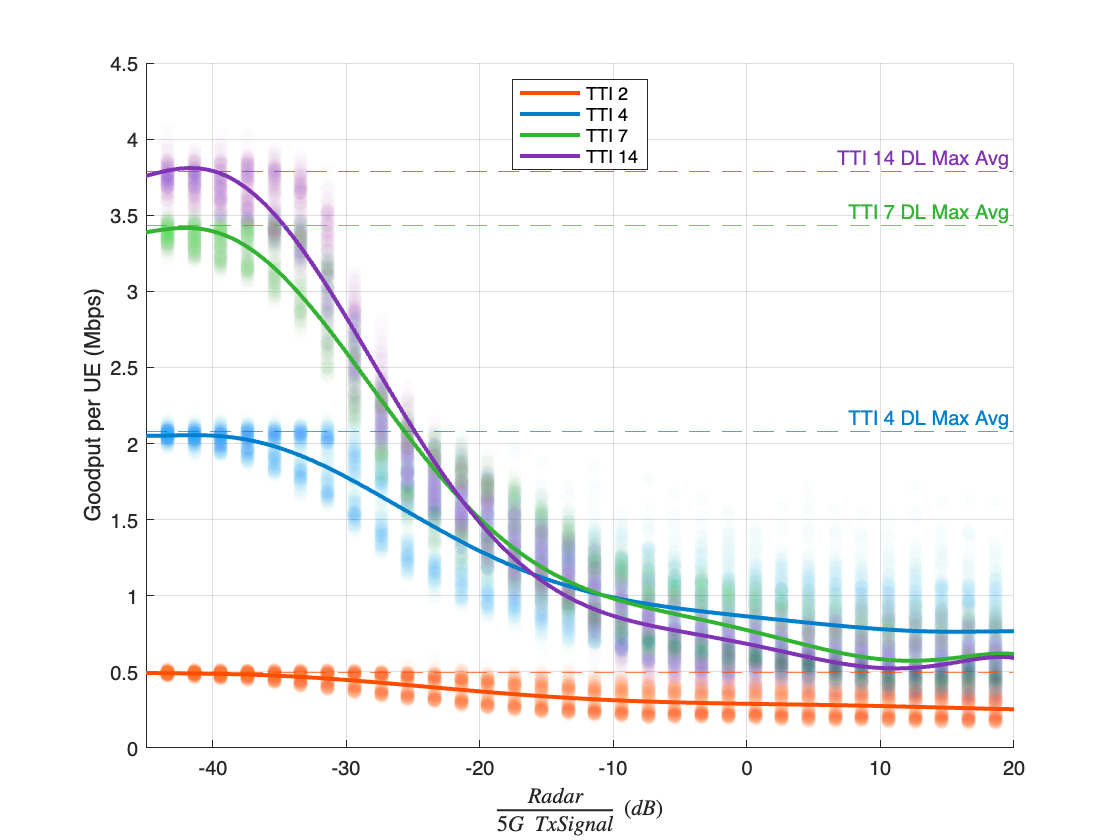

if radar_txHozScale
    tti2.(xvar) = radar0 + tti2.(xvar)-tx5Gsignal;tti2.(yvar) = tti2.(yvar)*yscale;
    tti4.(xvar) = radar0 + tti4.(xvar)-tx5Gsignal;tti4.(yvar) = tti4.(yvar)*yscale;
    tti7.(xvar) = radar0 + tti7.(xvar)-tx5Gsignal;tti7.(yvar) = tti7.(yvar)*yscale;
    tti14.(xvar) = radar0 + tti14.(xvar)-tx5Gsignal;tti14.(yvar) = tti14.(yvar)*yscale;
    xlabel('$$ \frac{Radar}{5G\ Tx Signal} \ (dB)$$','interpreter','latex')
    xlim([-45 20])
else
    tti2.(xvar) =   tti2.(xvar);tti2.(yvar) = tti2.(yvar)*yscale;
    tti4.(xvar) =   tti4.(xvar);tti4.(yvar) = tti4.(yvar)*yscale;
    tti7.(xvar) =   tti7.(xvar);tti7.(yvar) = tti7.(yvar)*yscale;
    tti14.(xvar) =   tti14.(xvar);tti14.(yvar) = tti14.(yvar)*yscale;
    xlabel("PulseAtten")
end
% Plot scatter points with specific colors
tti2_plot = scatter(tti2.(xvar), tti2.(yvar), 50, 'filled', 'DisplayName', 'TTI 2', 'MarkerFaceColor', color1,'MarkerFaceAlpha', alpha_level);
tti4_plot =scatter(tti4.(xvar), tti4.(yvar), 50, 'filled', 'DisplayName', 'TTI 4', 'MarkerFaceColor', color2,'MarkerFaceAlpha', alpha_level);
tti7_plot = scatter(tti7.(xvar), tti7.(yvar), 50, 'filled', 'DisplayName', 'TTI 7', 'MarkerFaceColor', color3,'MarkerFaceAlpha', alpha_level);
tti14_plot = scatter(tti14.(xvar), tti14.(yvar), 50, 'filled', 'DisplayName', 'TTI 14', 'MarkerFaceColor', color4,'MarkerFaceAlpha', alpha_level);

tti2DLMax = yline(496696.0*yscale,'--','','LabelHorizontalAlignment','left', 'Color',color1);
tti4DLMax = yline(2081720.0*yscale,'--','TTI 4 DL Max Avg','LabelHorizontalAlignment','right', 'Color',color2);
tti7DLMax = yline(3430896.0*yscale,'--','TTI 7 DL Max Avg','LabelHorizontalAlignment','right', 'Color',color3);
tti14DLMax = yline(3785808.0*yscale,'--','TTI 14 DL Max Avg','LabelHorizontalAlignment','right', 'Color',color4);


% Add trendlines for TTI = 2, 4, and 7
% Trendline for TTI = 2
trendlineNumeral = 7;
[x_fit2, y_fit2] = setupTrendlines(tti2, trendlineNumeral,xvar,yvar);
[x_fit4, y_fit4] = setupTrendlines(tti4, trendlineNumeral,xvar,yvar);
[x_fit7, y_fit7] = setupTrendlines(tti7, trendlineNumeral,xvar,yvar);
[x_fit14, y_fit14] = setupTrendlines(tti14, trendlineNumeral,xvar,yvar);
tti2_trend = plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2');
tti4_trend = plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4');
tti7_trend = plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7');
tti14_trend = plot(x_fit14, y_fit14, '-', 'Color', color4, 'LineWidth', 2, 'DisplayName', 'TTI 14');



% Create legend
legend('Location', 'north');
legend([tti2_trend,tti4_trend,tti7_trend,tti14_trend])
saveFolder = 'Images/Plots/' ;
save_name = strcat(saveFolder,xvar, '_vs_', yvar,'20MHzPulseBW_3');
% saveas(gcf, strcat(save_name, '.png'));  % Save as PNG
hold off;

## PowerLevelGraphing


load("RadarPwrLevelAnalysis/IQData.mat")
simParameters.numerology = 1;
fs = 30720000;
simParameters.NumFramesSim = 5;
simParameters.radar.prf = 2000;
simParameters.radar.PulseWidth = 50e-6;
simParameters.radar.FreqOffset = 0e6;
simParameters.radar.BW =20e6;
freq = nlfmspec2freq(simParameters.radar.BW ,taylorwin(200,4,-35));
slotStartIdx = 0.3 * 15360;
% slotLength = symLgths(pulseSlotId);
a = zeros(1,slotStartIdx);
x = complex(a,0);
simParameters.radar.numPulses = ceil((simParameters.NumFramesSim *10 * 1e-3)/simParameters.radar.prf);
fm = phased.CustomFMWaveform('SampleRate',fs, ...
    'PulseWidth',simParameters.radar.PulseWidth, ...
    'NumPulses',simParameters.radar.numPulses, ...
    'PRF',simParameters.radar.prf, ...
    'FrequencyModulation',freq, ...
    'PRF',simParameters.radar.prf, ...
    'FrequencyOffsetSource','Property', ...
    'FrequencyOffset',simParameters.radar.FreqOffset, ...
    OutputFormat='Samples', ...
    NumSamples=(7680*2*simParameters.NumFramesSim*10*2^(simParameters.numerology)));

y = fm();
y = y(1:end-slotStartIdx);
% z = [x';y];
% spectrogram(z,100,0,nfft1,fs,'centered','yaxis') 


simParameters.radar.waveform = [x';y];
simParameters.radar.pulseIdxOffset_ms = (slotStartIdx/length(simParameters.radar.waveform) ) * 1e-3 ;

% Assuming x and y are defined
pulse = [x'; y];  % Combine x and y into the pulse array

%apply SignalAttenuation
simParameters.pulseAttenuation = -50; %db
pulse = db2mag(simParameters.pulseAttenuation)*pulse;

% Number of parts to divide into
n = simParameters.NumFramesSim*10*2^(simParameters.numerology);  % Example: divide into n parts

% Determine the size of each part
total_length = length(pulse);
part_length = floor(total_length / n);  % Length of each part

% Preallocate a cell array to store the parts
pulse_parts = cell(1, n);

% Divide the pulse into n parts
for i = 1:n
    start_idx = (i - 1) * part_length + 1;  % Start index of the current part
    if i == n
        % Last part includes any leftover elements
        end_idx = total_length;
    else
        end_idx = i * part_length;  % End index of the current part
    end
    pulse_parts{i} = pulse(start_idx:end_idx);  % Store the part in the cell array
end

pulse = pulse_parts;

txWaveform = pulse{1} + tx5gSignal;

CombPWR = 10 + 20 * log10(abs(mean(txWaveform)))

CombPWR = -60.7192

RadarPWR = 10 + 20 * log10(abs(mean(pulse{1})))

RadarPWR = -87.7770

tx5GPWR = 10 + 20 * log10(abs(mean(tx5gSignal)))

tx5GPWR = -60.3826



% signalAnalyzer(txWaveform,pulse{1},tx5gSignal,'SampleRate',fs);

% signalAnalyzer(pulse{1},'SampleRate',fs);
% signalAnalyzer(tx5gSignal,'SampleRate',fs);



function plotScatterWithTrendlines(xvar, yvar, tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level)
    % plotScatterWithTrendlines - Plots scatter points and trendlines for given x and y variables
    %
    % Syntax: plotScatterWithTrendlines(xvar, yvar, tti2, tti4, tti7, color1, color2, color3, alpha_level)
    %
    % Inputs:
    %   xvar       - String, name of the x-axis variable
    %   yvar       - String, name of the y-axis variable
    %   tti2       - Table, data for TTI 2
    %   tti4       - Table, data for TTI 4
    %   tti7       - Table, data for TTI 7
    %   color1     - Array, RGB color for TTI 2
    %   color2     - Array, RGB color for TTI 4
    %   color3     - Array, RGB color for TTI 7
    %   alpha_level - Double, transparency level for scatter points (0 to 1)
    %
    % Outputs:
    %   None (creates a plot and saves it to file)

    % Create figure
    figure;
    hold on;
    title('');
    xlabel(xvar, 'Interpreter', 'none');
    ylabel(yvar, 'Interpreter', 'none');

    % Plot scatter points with specific colors
    scatter(tti2.(xvar), tti2.(yvar), 50, 'filled', 'DisplayName', 'TTI 2', ...
        'MarkerFaceColor', color1, 'MarkerFaceAlpha', alpha_level);
    scatter(tti4.(xvar), tti4.(yvar), 50, 'filled', 'DisplayName', 'TTI 4', ...
        'MarkerFaceColor', color2, 'MarkerFaceAlpha', alpha_level);
    scatter(tti7.(xvar), tti7.(yvar), 50, 'filled', 'DisplayName', 'TTI 7', ...
        'MarkerFaceColor', color3, 'MarkerFaceAlpha', alpha_level);
    scatter(tti14.(xvar), tti14.(yvar), 50, 'filled', 'DisplayName', 'TTI 14', ...
        'MarkerFaceColor', color3, 'MarkerFaceAlpha', alpha_level);
    % Add trendlines for TTI = 2, 4, 7, and 14
    % Trendline for TTI = 2
    [x_fit2, y_fit2] = setupTrendlines(tti2, 2);
    plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');

    % Trendline for TTI = 4
    [x_fit4, y_fit4] = setupTrendlines(tti4, 2);
    plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4 Trendline');

    % Trendline for TTI = 7
    [x_fit7, y_fit7] = setupTrendlines(tti7, 2);
    plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7 Trendline');
    
    % Trendline for TTI = 14 / Slot Based
    [x_fit14, y_fit14] = setupTrendlines(tti7, 2);
    plot(x_fit14, y_fit14, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 14 Trendline');

    % Create legend
    legend('Location', 'northwest');

    % Save the plot
    saveFolder = 'Images/Plots/' ;
    save_name = strcat(saveFolder,xvar, '_vs_', yvar);


    saveas(gcf, strcat(save_name, '.png'));  % Save as PNG
    hold off;
end

function [x_fit, y_fit] = setupTrendlines(tti,numfit,xvar,yvar)
    p = polyfit(tti.(xvar), tti.(yvar), numfit);
    x_fit = linspace(min(tti.(xvar)), max(tti.(xvar)), 100);
    y_fit = polyval(p, x_fit);
    % plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');
end

function plotAll(xvar,yvar)
    figure;
    hold on;
    title('');
    xlabel(xvar,'Interpreter', 'none');
    ylabel(yvar,'Interpreter', 'none');
    
    % Plot scatter points with specific colors
    tti2_plot = scatter(tti2.(xvar), tti2.(yvar), 50, 'filled', 'DisplayName', 'TTI 2', 'MarkerFaceColor', color1,'MarkerFaceAlpha', alpha_level);
    tti4_plot = scatter(tti4.(xvar), tti4.(yvar), 50, 'filled', 'DisplayName', 'TTI 4', 'MarkerFaceColor', color2,'MarkerFaceAlpha', alpha_level);
    tti7_plot = scatter(tti7.(xvar), tti7.(yvar), 50, 'filled', 'DisplayName', 'TTI 7', 'MarkerFaceColor', color3,'MarkerFaceAlpha', alpha_level);
    tti14_plot = scatter(tti14.(xvar), tti14.(yvar), 50, 'filled', 'DisplayName', 'TTI 14', 'MarkerFaceColor', color4,'MarkerFaceAlpha', alpha_level);
    
    % Add trendlines for TTI = 2, 4, and 7
    % Trendline for TTI = 2
    [x_fit2, y_fit2] = setupTrendlines(tti2, 2,xvar,yvar);
    [x_fit4, y_fit4] = setupTrendlines(tti4, 2,xvar,yvar);
    [x_fit7, y_fit7] = setupTrendlines(tti7, 2,xvar,yvar);
    [x_fit14, y_fit14] = setupTrendlines(tti14, 2,xvar,yvar);
    
    plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');
    plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4 Trendline');
    plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7 Trendline');
    plot(x_fit14, y_fit14, '-', 'Color', color4, 'LineWidth', 2, 'DisplayName', 'TTI 14 Trendline');
    
    % Create legend
    legend('Location', 'northeast');
    
    hold off;
end